# Support Vector Machines for 2D Data

We will use Support Vector Machines (SVMs), a "black box" learning algorithm, to classify 2D data. 

You can import your own 2D dataset. However, I will provide exmaple 2D datasets to demonstate the implementation of our SVMs (one in which the data is linearly separable and one with a non-linear decision boundary). I generated both datasets. 

We'll start with a simple 2D dataset, which can be separated with a linear boundary. The data is plotted below, with "positive" examples indicated as "x" and "negative" examples indicated wtih "o". 

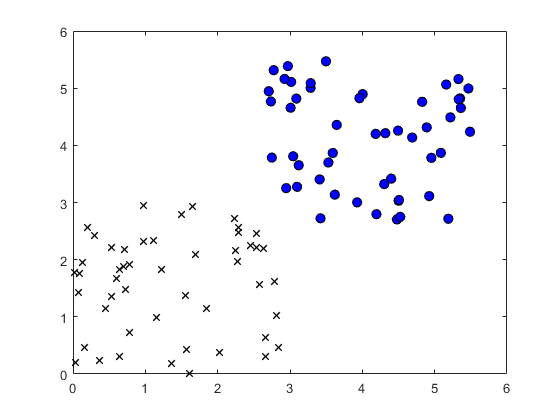

load('dataset1.mat');
figure; plotdata(X, y); 

We will use the [functionality](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) available in the MATLAB Statistics and Machine Learning toolbox to train our SVM using a linear kernel. 

[mdl,FitInfo] = fitclinear(X,y)

mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [2×1 double]
              Bias: 7.6847
            Lambda: 0.0100
           Learner: 'svm'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 0.0100
                 Objective: 0.0247
            IterationLimit: 1000
             NumIterations: 37
              GradientNorm: 0.0260
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 6.0612e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'Tolerance on coefficients satisfied.'}
                   History: []
                   FitTime: 0.0031
                    Solver: {'bfgs'}


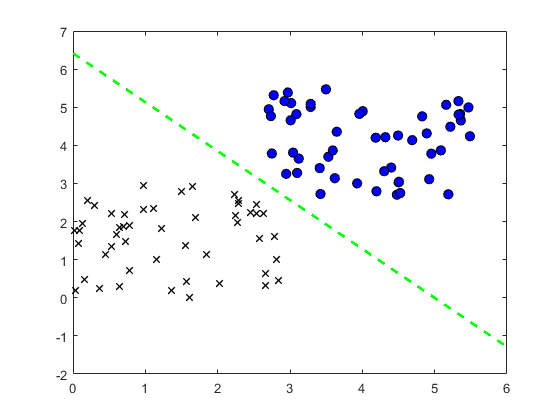

x = linspace(0,6);
f = @(x) -(x*mdl.Beta(1) + mdl.Bias)/mdl.Beta(2);
boundary = f(x);
plotdata(X, y); hold on;
plot(x,boundary,'g--','LineWidth',2,'DisplayName','Boundary'); hold off;

Our decision boundary clearly separates our data. 

What if we have a more complicated dataset, which requires non-linear classification? 

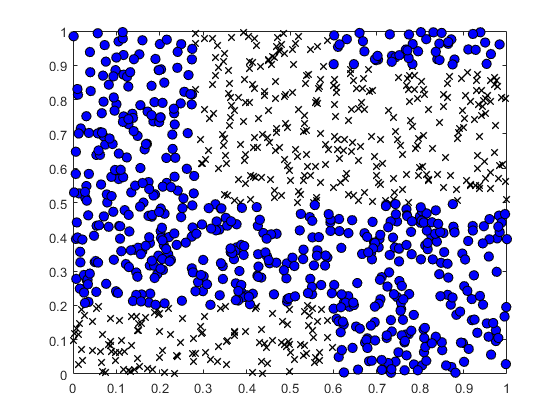

load('dataset2.mat');
plotdata(X,y)

We can observe that there is no linear decision boundary which will reasonably separate the positive and negative examples in our dataset. 

We can use a Gaussian kernel with our SVM to learn a non-linear decision boundary for our data. We will use the [functionality](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) available in the MATLAB Statistics and Machine Learning toolbox to train our SVM to fit a Gaussian kernel. I set the loss value, but feel free to modify for your own dataset!

lossval = 1; 
while lossval > 0.12
    [mdl,FitInfo] = fitckernel(X,y);
    lossval = loss(mdl,X,y)
end

lossval = 0.1360

lossval = 0.1940

lossval = 0.1550

lossval = 0.2090

lossval = 0.1620

lossval = 0.1660

lossval = 0.1190

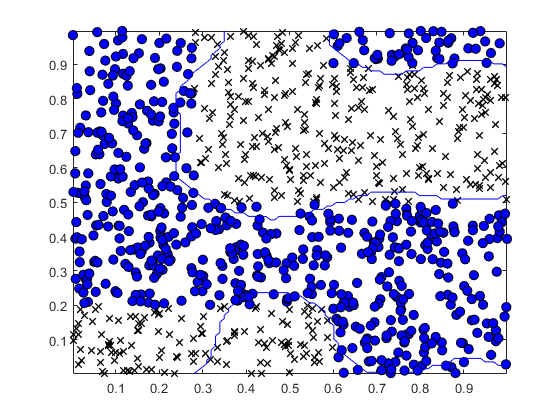

visualizeBoundary(X,y,mdl)

The the decision boundary found by the SVM with a Gaussian kernel is able to separate most of the positive and negative examples correctly!

In order to use this algorithm for your own data, simply load in your data above!